% пробую сгенерить си код

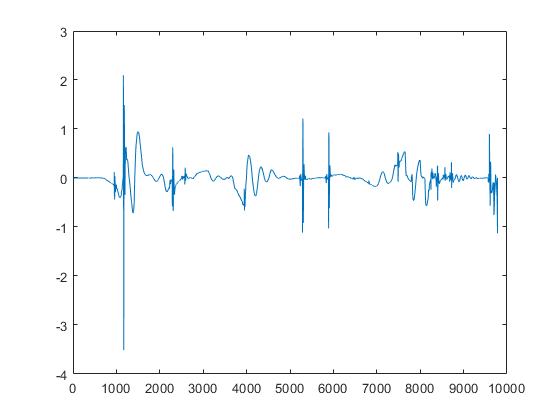

x=tYawAcc(:, 2);
plot(x)

nWht = 64

nWht = 64

n_section = 6

n_section = 6

nSectionPlus=7;
msp = zeros(64, 9);
load("kwhd.mat")

nnn = 1201;
y00 = 1:1201

y00 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


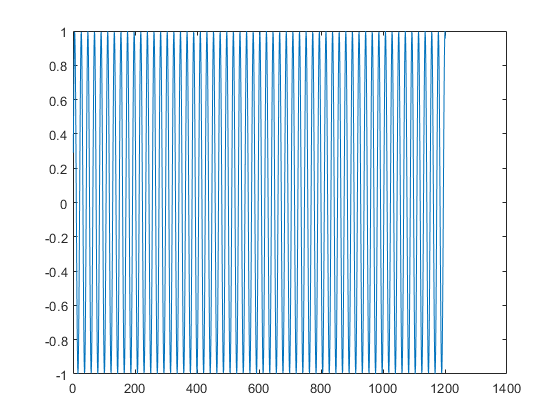

y01 = sin(3*2*pi/64*y00);
plot(y01)

x=y01;

wh_deg = WhDebagSimul();
msp(:,:)=0;

v=zeros(nnn);

for ix=1:nnn    %length(x)
%    [Y, Ynorm] = wh_deg.Step(x(i), 3);
    if ix>64
        iiiiii=1;
    end
    msp(2:nWht, 1) = msp(1:nWht-1, 1);
    msp(:, 2:6) = 0;
    msp(1,1) = x(ix);
    if mod(ix, 200)==0
        disp(ix)
    end
    k = 2;
    for i = 2: n_section
        sm_k = nWht / k;
        for k0=0 : k-1
            if mod(k0, 2) ==0
                i0=sm_k*k0+1: sm_k*(k0+1);
                msp(i0, i) = msp(i0, i-1) - msp(i0 + sm_k, i-1);
% for i0 = sm_k*k0+1: sm_k*(k0+1) msp(i0, i) = msp(i0, i-1) - msp(i0 + sm_k, i-1); end
            else
                i0 = sm_k*k0+1: sm_k*(k0+1);
                msp(i0, i) = msp(i0, i-1) + msp(i0 - sm_k, i-1);
% for i0 = sm_k*k0+1: sm_k*(k0+1)  msp(i0, i) = msp(i0, i-1) + msp(i0 - sm_k, i-1);  end
            end
        end
        k=k*2;        
    end
    
    for i=1:nWht
         if mod(i, 2) ~=0
             msp(i, nSectionPlus) = msp(i, nSectionPlus - 1)  - msp(i + 1, nSectionPlus - 1);
         else
             msp(i, nSectionPlus) = msp(i, nSectionPlus - 1) + msp(i - 1, nSectionPlus - 1);
         end
     end
  
     v0 = 0.0;
     for i=1:(nWht/2-1)
         i0 = i * 2;
         v0 =v0 +	abs(msp(i0 + 1, nSectionPlus)) + abs(msp(i0 + 2, nSectionPlus));
     end
     
     v(ix)=v0;
     
     if ix>=64
         msp(:, 8)=fwht(msp(:, 7));
         msp(:, 9)=abs(fwht(msp(:, 7)));
     end

end

nn = 64

disp(" расчет закончен ")


plot(v)